clear;

%Testing LPC function on a sample
%%%%%%%%%%%%%%%%%%%%
[f1,f1_fs]=audioread('f1.wav');
[lp_c,lp_rc]=extract_LPC(f1,f1_fs);
[mf_cc]=extract_mfcc(f1,f1_fs);

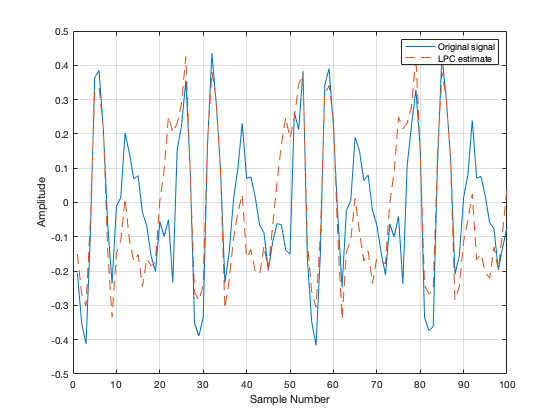

%Plotting estimated signal using LPC vs original signal 
est_x = filter([0 -lp_c(1,2:end)],1,f1(1:480));
plot(1:100,f1(381:480),1:100,est_x(end-100+1:end),'--')
grid
xlabel('Sample Number')
ylabel('Amplitude')
legend('Original signal','LPC estimate')

%The HelperAN4Download function downloads the dataset and converts the raw files to FLAC. 
% The speech files are partitioned into subdirectories based on the labels corresponding 
% to the speakers.
%dataDir = HelperAN4Download;
dataDir='/Volumes/Partition 2/M Eng course Fall/ADSP/project/experiments/an4/wav/flacData';

%Creating datastore object which allows to collect necessary files of a file format and read them
ads = audioDatastore(dataDir,'IncludeSubfolders',true, ...
    'FileExtensions','.flac', ...
    'LabelSource','foldernames');
%Splitting the dataset into training and testing set
[adsTrain, adsTest] = splitEachLabel(ads,0.8);
%getting count of the samples per label in training set
trainDatastoreCount = countEachLabel(adsTrain)

trainDatastoreCount = 11×2 table
    Label     Count
    ______    _____

    fejs       10  
    fmjd       10  
    fsrb       10  
    ftmj       10  
    fwxs       10  
    mcen       10  
    mrcb       10  
    msjm       10  
    msjr       10  
    msmn        7  
    vineet     10  


%getting count of the samples per label in test set
testDatastoreCount = countEachLabel(adsTest)

testDatastoreCount = 11×2 table
    Label     Count
    ______    _____

    fejs        3  
    fmjd        3  
    fsrb        3  
    ftmj        3  
    fwxs        2  
    mcen        3  
    mrcb        3  
    msjm        3  
    msjr        3  
    msmn        2  
    vineet      3  


%Reading a sample file and playing it
[sampleTrain, dsInfo] = read(adsTrain);
sound(sampleTrain,dsInfo.SampleRate)
%reset the iteration pointer to start from beginning
reset(adsTrain)

%Getting the sample rate
fs = dsInfo.SampleRate;
%defining the window length and overlap length
windowLength = round(0.03*fs);
overlapLength = round(0.025*fs);
%initialise the features and labels
features = [];
labels = [];
%Going through all the files in a loop
while hasdata(adsTrain)
    %Reading file and info
    [audioIn,dsInfo] = read(adsTrain);
    %adding noise
    snr=5;
    audioIn = awgn(audioIn,snr,'measured');
    %calling function to extract LPC and reflection coefficients
    [lpc,lprc] = extract_LPC(audioIn,fs);
    %calling function to extract MFCC
    melC = extract_mfcc(audioIn,fs);
    %to merge LPC and MFCC features we take minimum length out of two
    f_size=min(height(lpc),height(melC));
    %Merging the features in a matrix for this sample
    feat = [melC(1:f_size,:) lpc(1:f_size,2:end) lprc(1:f_size,:)];
    %Updating labels for each sample
    label = repelem(dsInfo.Label,size(feat,1));
    %Updating the features matrix and labels
    features = [features;feat];
    labels = [labels,label];
end


% Normalizing the features
M = mean(features,1);
S = std(features,[],1);
features = (features-M)./S;

%Training the K-nearest neighbor (KNN) classifier
trainedClassifier = fitcknn( ...
    features, ...
    labels', ...
    'Distance','euclidean', ...
    'NumNeighbors',5, ...
    'DistanceWeight','squaredinverse', ...
    'Standardize',false, ...
    'ClassNames',unique(labels));

%Performing the 5-fold stratified cross validation
k = 5;
group = labels;
c = cvpartition(group,'KFold',k); 
partitionedModel = crossval(trainedClassifier,'CVPartition',c);

%Calculating the validation accuracy
validationAccuracy = 1 - kfoldLoss(partitionedModel,'LossFun','ClassifError');
fprintf('\nValidation accuracy = %.2f%%\n', validationAccuracy*100);


Validation accuracy = 72.23%


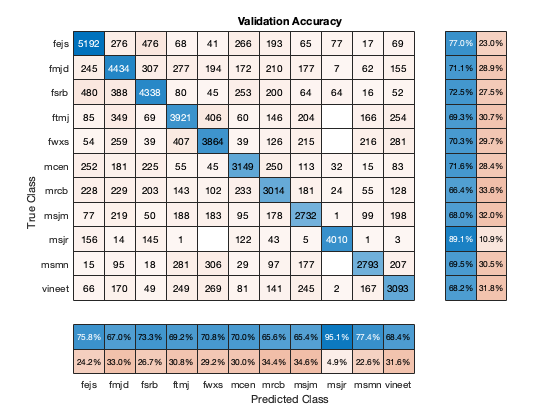

%Visualize the confusion chart
validationPredictions = kfoldPredict(partitionedModel);
figure
cm = confusionchart(labels,validationPredictions,'title','Validation Accuracy');
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';

%Testing the model on test data
features = [];
labels = [];
numVectorsPerFile = [];
while hasdata(adsTest)
    [audioIn,dsInfo] = read(adsTest);
    %adding noise
    snr=5;
    audioIn = awgn(audioIn,snr,'measured');
    %calling function to extract LPC and reflection coefficients
    [lpc,lprc] = extract_LPC(audioIn,fs);
    %calling function to extract MFCC
    melC = extract_mfcc(audioIn,fs);
    %to merge LPC and MFCC features we take minimum length out of two
    f_size=min(height(lpc),height(melC));
    %Merging the features in a matrix for this sample
    feat = [melC(1:f_size,:) lpc(1:f_size,2:end) lprc(1:f_size,:)];
   
    %Updating labels for each sample
    label = repelem(dsInfo.Label,size(feat,1));
    numVectorsPerFile = [numVectorsPerFile,size(feat,1)];
    %Updating the features matrix and labels
    features = [features;feat];
    labels = [labels,label];
end
% Normalizing the features
M = mean(features,1);
S = std(features,[],1);
features = (features-M)./S;

prediction = predict(trainedClassifier,features);
prediction = categorical(string(prediction));

%Calculating the frame wise test accuracy
correct=0;
for k =1:length(labels)
    if labels(k)==prediction(k)
        correct=correct+1;
    end
end
test_accuracy=(correct/length(labels))*100;
fprintf('\nTest accuracy for frames = %.2f%%\n', test_accuracy);


Test accuracy for frames = 31.53%


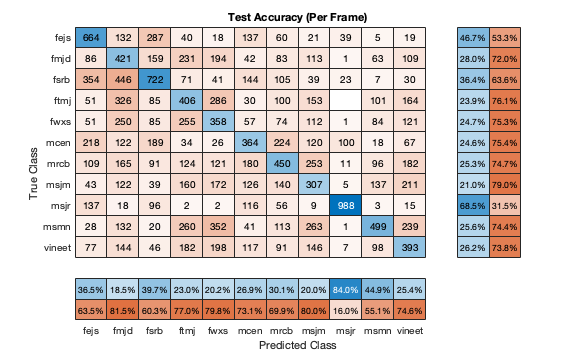

figure('Units','normalized','Position',[0.4 0.4 0.4 0.4])
cm = confusionchart(labels,prediction,'title','Test Accuracy (Per Frame)');
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';

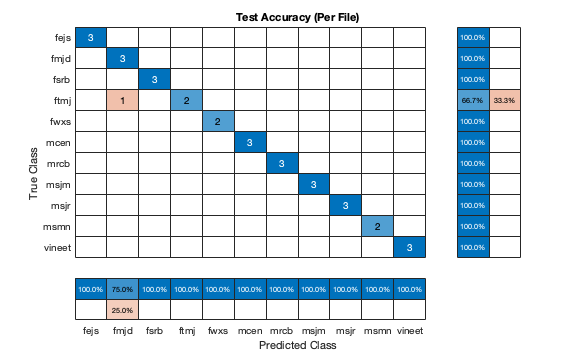

%The above predictions are for frames and not samples
%Converting predictions into sample wise prediction using mode
r2 = prediction(1:numel(adsTest.Files));
idx = 1;
for ii = 1:numel(adsTest.Files)
    r2(ii) = mode(prediction(idx:idx+numVectorsPerFile(ii)-1));
    idx = idx + numVectorsPerFile(ii);
end

figure('Units','normalized','Position',[0.4 0.4 0.4 0.4])
cm = confusionchart(adsTest.Labels,r2,'title','Test Accuracy (Per File)');
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';

function[lp_c,lp_rc]=extract_LPC(audioIn,fs)   
    windowLength = round(0.03*fs);
    overlapLength = round(0.025*fs);
    %Creating a pre-emphasis filter
    preEmphasisFilter = dsp.FIRFilter(...
            'Numerator', [1 -0.95]);
    i=1;
    sig_start=1;
    sig_stop=windowLength;
    while (sig_stop<length(audioIn))
        % Reading the input
        sig = audioIn(sig_start:sig_stop,1);
    
        % Performing pre-emphasis
        sigpreem   = preEmphasisFilter(sig);
        %Applying hamming window
        hammingwin = hamming(windowLength);
        sigwin     = hammingwin.*sigpreem;
    
        %The rule of thumb for the LPC order is sampling rate in kHz + 3 or 4
        order=floor(fs/1000)+3;
        % Getting the Autocorrelation
        sigacf = xcorr(sigwin, order-1, 'biased');
        sigacf = sigacf(order:end);
    
        % Claculating the reflection coefficients using the Levinson Durbin recursion.
        % It returns both the polynomial coefficients and reflection coefficients. 
        [sigA, ~, sigK] = levinson(sigacf); % Levinson-Durbin
        lp_c(i,:)=sigA;
        lp_rc(i,:)=sigK;
        i=i+1;
        sig_start=sig_stop-overlapLength+1;
        sig_stop=sig_start+windowLength-1;
    end
end

function[melcc]=extract_mfcc(audioIn,fs)
    %MFCC extraction
    %Converting the audio signal to a frequency-domain representation using 30 ms windows with 15 ms overlap.
    windowLength = round(0.03*fs);
    overlapLength = round(0.025*fs);
    
    %Creating a pre-emphasis filter
    preEmphasisFilter = dsp.FIRFilter(...
            'Numerator', [1 -0.95]);
    audioIn= preEmphasisFilter(audioIn);
    %Performing short time fourier transform
    S = stft(audioIn,"Window",hann(windowLength,"periodic"),"OverlapLength",overlapLength,"FrequencyRange","onesided");
    S = abs(S);
    %Design a one-sided frequency-domain mel filter bank. Apply the filter bank to the frequency-domain representation to create a mel spectrogram.
    filterBank = designAuditoryFilterBank(fs,'FFTLength',windowLength);
    melSpec = filterBank*S;
    %Call cepstralCofficients with the mel spectrogram to create MFCC.
    melcc = cepstralCoefficients(melSpec);
    
end

function dataDir = HelperAN4Download
%HelperAN4Download Download and extract the AN4 dataset. 
% The dataset is downloaded from:
%  http://www.speech.cs.cmu.edu/databases/an4
%
% The speech files corresponding to 5 male and 5 female speakers are
% retained. The rest of the speech files are deleted. The output of the
% function is the path to the 'an4' parent directory in the dataset.
%
% This function HelperAN4Download is only in support of
% SpeakerIdentificationExample. It may change in a future release.

%   Copyright 2017 The MathWorks, Inc.

url = 'http://www.speech.cs.cmu.edu/databases/an4/an4_raw.littleendian.tar.gz';
d = '/Volumes/Partition 2/M Eng course Fall/ADSP/project/experiments/';
fs = 16e3;

% Download and extract if it hasn't already been done.
unpackedData = fullfile(d, 'an4');
d1 = fullfile(unpackedData, 'wav','flacData');
if ~exist(unpackedData, 'dir')
    fprintf('Downloading AN4 dataset... ');
    untar(url, d);
    fprintf('done.\n');
    mkdir(d1);
end

% Reduce dataset to 5 female and 5 male speakers
validDirs = {'fejs', 'fmjd', 'fsrb', 'ftmj', 'fwxs', ...
             'mcen', 'mrcb', 'msjm', 'msjr', 'msmn', '.', '..'};
d3 = fullfile(unpackedData, 'wav', 'an4_clstk');
listing = dir(d3);
l = {listing(:).name};

if length(l) > length(validDirs)
    fprintf('Reducing dataset to 5 females and 5 males... ');
    for idx = 3:length(l)
        if ~ismember(l{idx}, validDirs)
            rmdir(fullfile(d3,l{idx}),'s');
        else
           mkdir(fullfile(d1,l{idx}));
           list = dir(fullfile(d3,l{idx}));
           for i = 3:length(list)
               filename = list(i).name;
               fname = fullfile(d3,l{idx},filename);
               
               fullfilename = fullfile(d1,l{idx},filename);
               
               % % Read binary data (stored as int16)
               
               fid = fopen(fname,'r');
               xint = int16(fread(fid,[1,inf],'int16')).';
               fclose(fid);
               
               % Scale int16 to double
               x = double(xint)*2^-15;
               % % Convert to flac and write it
               newname = strrep(fullfilename,'.raw','.flac');
               audiowrite(newname,x,fs);
           end
        end
    end
    rmdir(fullfile(unpackedData, 'wav', 'an4test_clstk'),'s');
    fprintf('done.\n');
end

dataDir = d1;

end
